# Homework 8

Ross Smyth

clear, clc, close all

Default plant and relevant paramters below.

plant = tf(296, [1, 53, 592, 0])

plant =
 
          296
  --------------------
  s^3 + 53 s^2 + 592 s
 
Continuous-time transfer function.



wanted_poles = 21 * exp(1i * (acos(0.7) + pi/2))

wanted_poles = -14.9970 + 14.7000i

cur_ang = angle(evalfr(plant, wanted_poles)) * 180 / pi

cur_ang = 104.5838

needed = 180 - cur_ang

needed = 75.4162

## A.

Graphically derived pole and zero:


$$\begin{array}{l}
\mathrm{pole}\approx -47\ldotp 2\\
\mathrm{zero}\approx -12
\end{array}$$


comp1     = zpk(-12, -47.2, 1);
part_a.tf = plant * comp1;

k           = 1 / abs(evalfr(plant * comp1, wanted_poles));
part_a.loop = feedback(comp1 * plant * k, 1);

[part_a.wn, part_a.zeta] = damp(part_a.loop);
damp(part_a.loop)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -8.31e+00                 1.00e+00       8.31e+00         1.20e-01    
 -1.53e+01 + 1.49e+01i     7.17e-01       2.13e+01         6.54e-02    
 -1.53e+01 - 1.49e+01i     7.17e-01       2.13e+01         6.54e-02    
 -6.13e+01                 1.00e+00       6.13e+01         1.63e-02    


Based upon the calculated close-loop poles shown above, the target damping ratio and natrual frequency are nearly met with this graphical technique.

## B.

Graphically derived poles and zeros:


$$\begin{array}{l}
\mathrm{poles}\approx -28,-28\\
\mathrm{zero}\approx -16,-16
\end{array}$$


comp2     = zpk(-16, -28, 1);
part_b.tf = plant * comp2 * comp2;

k           = 1 / abs(evalfr(plant * comp2 * comp2, wanted_poles));
part_b.loop = feedback(comp2 * comp2 * plant * k, 1);

[part_b.wn, part_b.zeta] = damp(part_b.loop);
damp(part_b.loop)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -9.97e+00                 1.00e+00       9.97e+00         1.00e-01    
 -1.60e+01                 1.00e+00       1.60e+01         6.25e-02    
 -1.50e+01 + 1.47e+01i     7.14e-01       2.10e+01         6.68e-02    
 -1.50e+01 - 1.47e+01i     7.14e-01       2.10e+01         6.68e-02    
 -5.31e+01                 1.00e+00       5.31e+01         1.88e-02    


The above calculated natrual frequencies and damping ratios are close to the desired values.

## C.

cancel  = zpk(-16, [], 1);
cur_ang = angle(evalfr(plant * cancel, wanted_poles)) * 180 / pi

cur_ang = -169.3195

needed  = mod(cur_ang - 180, 180)

needed = 10.6805

Graphically derived pole and zero:


$$\begin{array}{l}
\mathrm{poles}\approx -19\ldotp 2\\
\mathrm{zero}\approx -22\ldotp 5
\end{array}$$


comp3     = zpk(-22.5, -19.2, 1);
part_c.tf = plant * comp3 * cancel * k;

k           = 1 / abs(evalfr(plant * comp3 * cancel, wanted_poles));
part_c.loop = feedback(part_c.tf, 1);

[part_c.wn, part_c.zeta] = damp(part_c.loop);
damp(part_c.loop)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.60e+01                 1.00e+00       1.60e+01         6.25e-02    
 -1.49e+01 + 1.47e+01i     7.11e-01       2.09e+01         6.72e-02    
 -1.49e+01 - 1.47e+01i     7.11e-01       2.09e+01         6.72e-02    
 -2.64e+01                 1.00e+00       2.64e+01         3.78e-02    


The above calculated natrual frequencies and damping ratios are close to the desired values.

## Comparison

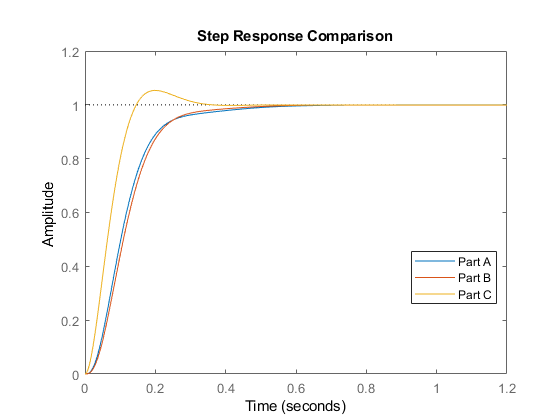

figure()
hold on
step(part_a.loop)
step(part_b.loop)
step(part_c.loop)
title('Step Response Comparison')
legend({'Part A', 'Part B', 'Part C'}, 'location', 'best')
hold off

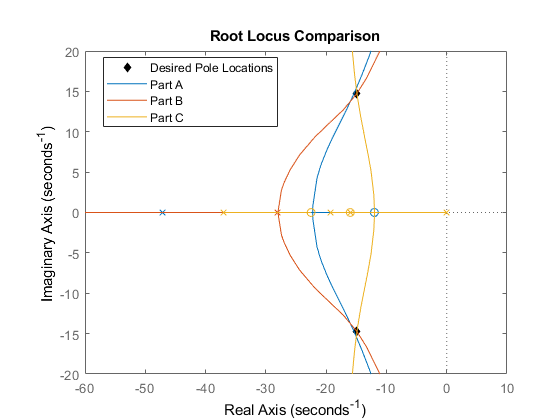

figure()
hold on
scatter(real([wanted_poles, wanted_poles]), imag([wanted_poles, -wanted_poles]), 'kd', 'filled')
rlocus(part_a.tf, part_b.tf, part_c.tf)
title('Root Locus Comparison')
axis([-60, 10, -20, 20])
legend({'Desired Pole Locations', 'Part A', 'Part B', 'Part C'}, 'location', 'best')
hold off

part_a.step = rows2vars(struct2table(stepinfo(part_a.loop, 'RiseTimeLimits', [0.01, 0.99], 'SettlingTimeThreshold', 0.01)));
part_a.step.Properties.VariableNames = {'Label', 'Part A'};
part_b.step = rows2vars(struct2table(stepinfo(part_b.loop, 'RiseTimeLimits', [0.01, 0.99], 'SettlingTimeThreshold', 0.01)));
part_b.step.Properties.VariableNames = {'Label', 'Part B'};
part_c.step = rows2vars(struct2table(stepinfo(part_c.loop, 'RiseTimeLimits', [0.01, 0.99], 'SettlingTimeThreshold', 0.01)));
part_c.step.Properties.VariableNames = {'Label', 'Part C'};

stats = join(join(part_a.step, part_b.step), part_c.step);
stats.Label = [];
label = {'Rise Time (s)',
        'Settling Time (s)',
        'Settling Min'
        'Settling Max',
        'Overshoot',
        'Undershoot',
        'Peak',
        'Peak Time (s)',
        'Min Integration Time (s)'};

% Assuming 0.5% error and Euler integration (worst case).
int_time = @(wn) 2 * 0.005 / max(wn);

stats = [stats; {int_time(part_a.wn), int_time(part_b.wn), int_time(part_c.wn)}];
stats.Properties.RowNames = label

stats = 9×3 table
                                  Part A        Part B        Part C  
                                __________    __________    __________

    Rise Time (s)                  0.48313       0.43183       0.13556
    Settling Time (s)              0.49952       0.44975       0.31025
    Settling Min                   0.99006        0.9901       0.99082
    Settling Max                   0.99996         0.999        1.0535
    Overshoot                            0             0        5.3505
    Undershoot                           0             0             0
    Peak                           0.99996         0.999        1.0535
    Peak Time (s)                   1.1703       0.67467       0.19794
    Min Integration Time 